# Module 9b: Nearest neighbour analysis (NeNA) localization precision

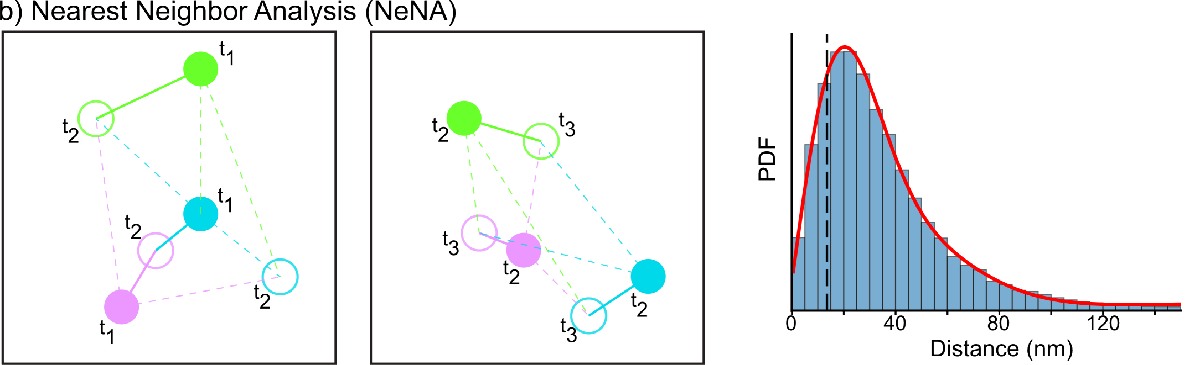

A method to calculate the localization precision of a dataset is to use NeNA. The underlying idea is that individual fluorophores will remain non-moving, even if they emit in multiple consequetive frames. This means that their 'apparent movement' over multiple frames is a measure for the localization precision.

## Variable initiation

clear all
% We specify the path to our file. 
file_path = 'Data/localization_file.txt';

% We load a localization file via the readmatrix function
data = commonFunctions.readTXTRapidSTORM(file_path);

## Nearest-neighbour distance calculation

After loading the data, we perform a nearest-neighbour linking procedure introduced in **module 3**. This time, the frame-to-frame linkage of immovable fluorophores provides information about the localization accuracy of every emitter.

%We perform nearest-neighbour finding as shown in Module 4a. The
%nearest-neighbour information is needed, because the average 'movement' of
%immobile particles is a measure for the localization accuracy
maxDistance = 150;
tracked_data = [data zeros(size(data,1),2)];
tracksCounter = 1;
for fr = 0:max(tracked_data(:,1))-1
    [tracked_data,tracksCounter] = commonFunctions.creating_trajectories(tracked_data,fr,fr+1,maxDistance,tracksCounter);
end

## Separation of fluorophores

Our dataset consists of two kinds of fluorophores (a fluorescent protein fused to RNA polymerase and fiducial markers). It is critical to separate both from each other, because they will have very different localization accuracies (the fiducial markers are much brighter). We can seperate them easily on intensity. First, we plot intensity histograms to observe where to split between the two populations.

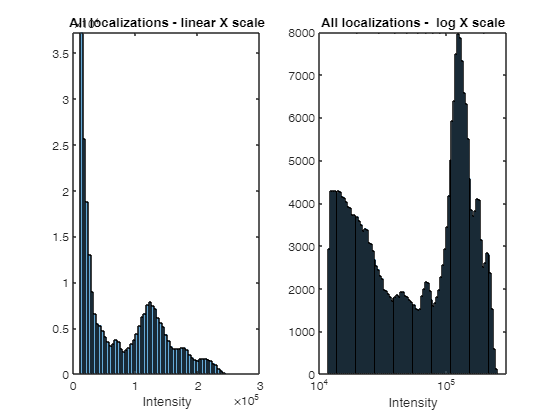

figure()
subplot(1,2,1)
%We first plot the data on a linear x-axis
histogram(tracked_data(:,4),100)
title('All localizations - linear X scale')
xlabel('Intensity')
%We specify the x-axis to a certain range
axis([0 3e5 0 inf])
subplot(1,2,2)
%We also plot the data on a logarithmic x-axis to showcase the two peaks
histogram(tracked_data(:,4),logspace(log10(1e4),log10(3e5),100))
title('All localizations -  log X scale')
xlabel('Intensity')
set(gca,'XScale','log')

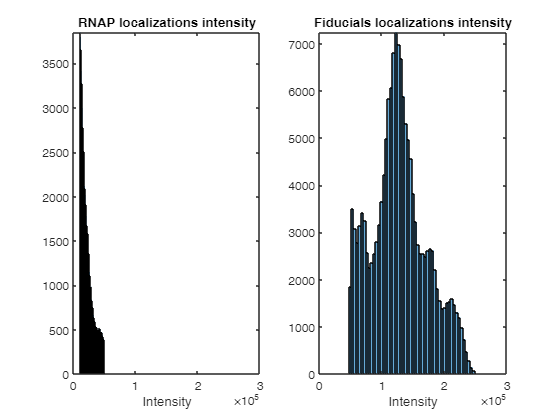

% We can split the data quite accurately at 50.000 intensity, and we can
% show them both side-by-side:
rnap = tracked_data(tracked_data(:,4) < 50000,:);

% In a similar way we treat fiducial markers. 
% This time we take only events above 50000 AU of intensity.
fiducials = tracked_data(tracked_data(:,4) >= 50000,:);

%Now we also visualise these two
figure()
subplot(1,2,1)
histogram(rnap(:,4),100)
title('RNAP localizations intensity')
xlabel('Intensity')
%We specify the x-axis to a same range as before
axis([0 3e5 0 inf])
subplot(1,2,2)
histogram(fiducials(:,4),100)
title('Fiducials localizations intensity')
xlabel('Intensity')
%We specify the x-axis to a same range as before
axis([0 3e5 0 inf])

## NeNA localization precision determination

Now we create a fitting function that contains NeNA formula (more details about this distribution can be found in [https://doi.org/10.1007/s00418-014-1192-3](https://doi.org/10.1007/s00418-014-1192-3) ): 


$$y=\frac{r}{2\cdot a^2 }\cdot e^{\frac{-r^2 }{4\cdot a^2 }} \cdot A+\frac{F}{w\cdot \sqrt{\frac{\pi }{2}}}\cdot e^{-2\cdot {\left(\frac{r-\textrm{rc}}{w}\right)}^2 } +O\cdot r$$


 The histogram data of RNAP is fit with this formula.

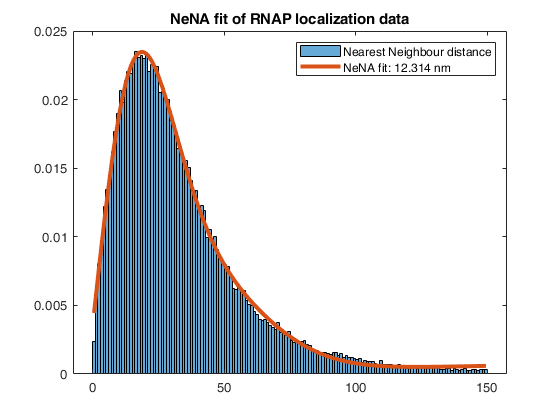

%First we find the JDs of the RNAP, filtering out zero-values
jds_rnap = rnap(rnap(:,6)>0,6);

% We plot a histogram of next-frame nearest neighbor distances
figure()
h1 = histogram(jds_rnap, 150, 'Normalization','Probability','DisplayName','Nearest Neighbour distance');
% We also calculate the center of every bin of this histogram - 
% this is done by removing the first entry, and then subtracting half-width bin from every entry
x = h1.BinEdges(2:end);
x = x-x(1)/2;

% We have to create the fittype based on the NeNA_model specified below
ft = fittype('(r./(2.*a.*a)).*exp((-1).*r.*r./(4.*a.*a)).*A + (F/(w*sqrt(pi/2))) .* exp(-2.*((r-rc)./w).*((r-rc)./w)) + O.*r','independent','r');
% As the distribution is characterized by six parameters it is highly advised 
% to provide inital values for each paramter.
% We have to these enter initial points (StartPoints) in the order [A,F,O,a,rc,w]
% (alphabetically, capitalization-sensitive).
NeNAfit = fit(x', h1.Values', ft, 'StartPoint', [0.5, 0.5, 1, 15, 15, 100]);
% plot( f, x, y ) 
hold on
plot(x,NeNAfit(x),'DisplayName',['NeNA fit: ' num2str(NeNAfit.a) ' nm'],'LineWidth',3)
legend()
title('NeNA fit of RNAP localization data')

We repeat this with the fiducial markers

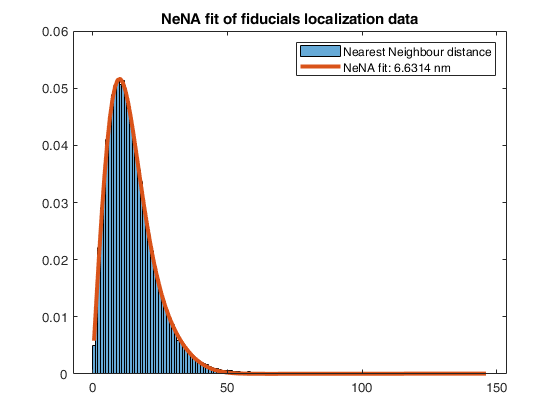

%First we find the JDs of the fiducials, filtering out zero-values
jds_fiducials = fiducials(fiducials(:,6)>0,6);

% We plot a histogram of next-frame nearest neighbor distances
figure()
h1 = histogram(jds_fiducials, 150, 'Normalization','Probability','DisplayName','Nearest Neighbour distance');
% We also calculate the center of every bin of this histogram - 
% this is done by removing the first entry, and then subtracting half-width bin from every entry
% Note that the edges of every bin in histogram h1 are stored as h1.BinEdges
x = h1.BinEdges(2:end);
x = x-x(1)/2;

% We have to create the fittype based on the NeNA_model specified below
ft = fittype('(r./(2.*a.*a)).*exp((-1).*r.*r./(4.*a.*a)).*A + (F/(w*sqrt(pi/2))) .* exp(-2.*((r-rc)./w).*((r-rc)./w)) + O.*r','independent','r');
% As the distribution is characterized by six parameters it is highly advised 
% to provide inital values for each paramter.
% We have to these enter initial points (StartPoints) in the order [A,F,O,a,rc,w]
% (alphabetically, capitalization-sensitive).
% Note that the y-values of the histogram h1 are stored as h1.Values.
NeNAfit = fit(x', h1.Values', ft, 'StartPoint', [0.5, 0.5, 1, 15, 15, 100]);
% plot( f, x, y ) 
hold on
plot(x,NeNAfit(x),'DisplayName',['NeNA fit: ' num2str(NeNAfit.a) ' nm'],'LineWidth',3)
legend()
title('NeNA fit of fiducials localization data')